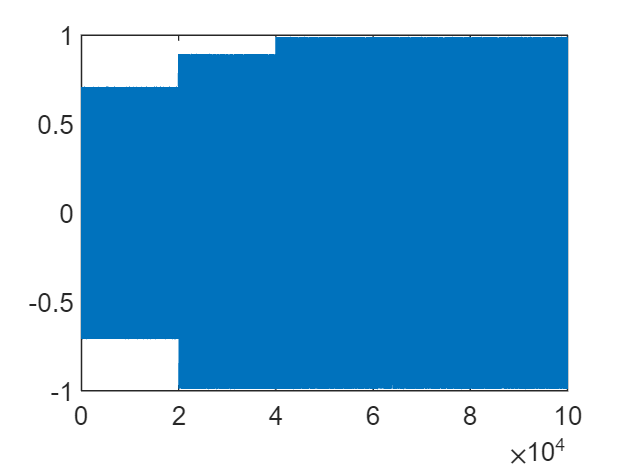

clc
clear

Fs = 20000;
T = 1/Fs;
r =24;
Tc = 1;

t =0:T:Tc-T;

x1 = cos(2*pi*1000*t+pi/4);
x2 = cos(2*pi*2000*t+pi/4);
x3 = cos(2*pi*3000*t+pi/4);
x4 = cos(2*pi*4000*t+pi/4);
x5 = cos(2*pi*5000*t+pi/4);

x = [x5 x4 x3 x2 x1];

figure();
plot(x);

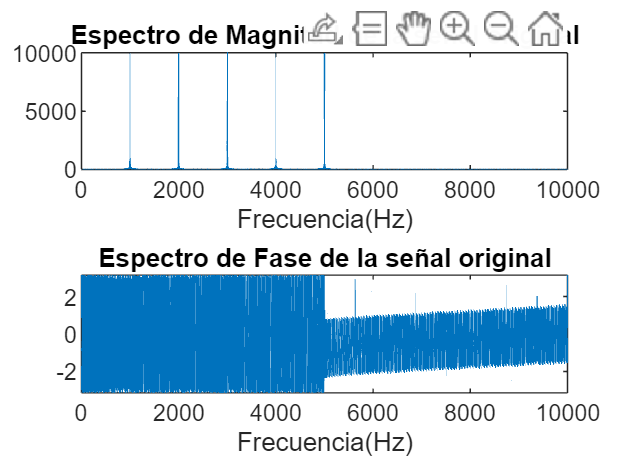


[X,FREC] = fourier(x,Fs);

figure();
subplot(2,1,1);
plot(FREC,abs(X));
title("Espectro de Magnitud de la señal original");
xlabel("Frecuencia(Hz)");

subplot(2,1,2);
plot(FREC,angle(X));
title("Espectro de Fase de la señal original");
xlabel("Frecuencia(Hz)");

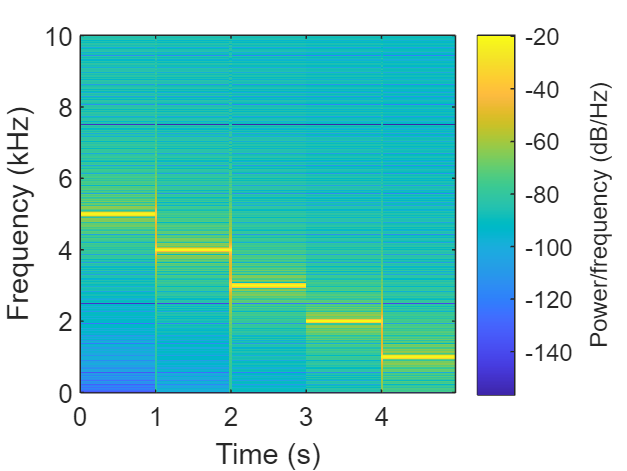


%calculo de espectrograma
TV = 30/1000;
NTV = Fs*TV;
ventana = hamming(NTV);
puntos_fourier = 2^nextpow2(NTV);

figure();
spectrogram(x,ventana,0,puntos_fourier,Fs,"yaxis");